# Data Collection for Air Levitation System

Clearing work space and setting up the file path

clear;
clc;
cd 'C:\Users\auw_a\OneDrive - Higher Colleges of Technology\Research\Air Levitating Control System'

## Creating objects for Arduino and Ultrasonic Sensor

Arduino Motor Shield:    Brake pin = 8; Direction pin = 13

Ultrasonic Sensor: Trigger = 4; Echo = 2

% creating Object for the Arudino with required Libraries
a = arduino('COM10','Uno',"Libraries","Ultrasonic") 

Updating server code on board Uno (COM10). This may take a few minutes.


a =   arduino with properties:

                  Port: 'COM10'
                 Board: 'Uno'
         AvailablePins: {'D2-D13', 'A0-A5'}
  AvailableDigitalPins: {'D2-D13', 'A0-A5'}
      AvailablePWMPins: {'D3', 'D5-D6', 'D9-D11'}
   AvailableAnalogPins: {'A0-A5'}
    AvailableI2CBusIDs: [0]
             Libraries: {'Ultrasonic'}
Show all properties



% Creating Ultrasonic Sensor obj with four pins
ultrasonic = ultrasonic(a,'D4','D2')       

ultrasonic =   Ultrasonic with properties:

    TriggerPin: 'D4'
       EchoPin: 'D2'



writeDigitalPin(a,'D8',0);      % Brake Pin
writeDigitalPin(a,'D13',1);     % Direction Pin


## Initializing Variables

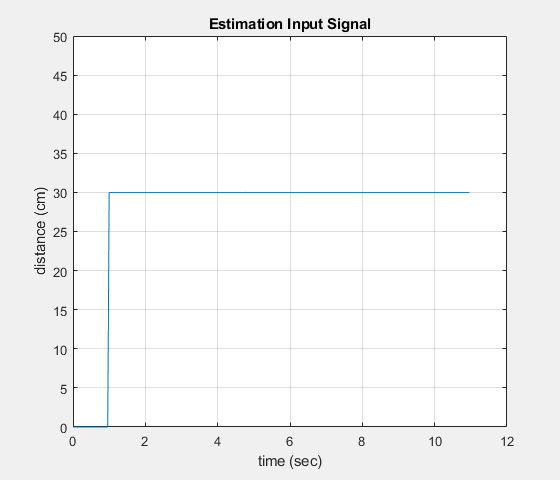

k = 30;             % proportional gain
step_time = 0.04;   % sample time

t = (0:step_time:11)';        % runtime

dis_est = zeros(length(t), 1);

% set point signal
a0 = zeros(1/step_time, 1);
a1 = 30*ones((1/step_time)*10, 1);
setpoint = [a0; a1];

% plotting signal
plot(t(1:end-1), setpoint);
ylim([0 50]);
grid on;
xlabel("time (sec)");
ylabel("distance (cm)");
title("Estimation Input Signal")


% Controller output saturation limits
upper_limit = 255;
lower_limit = 80;

## Setting up the plot Environment

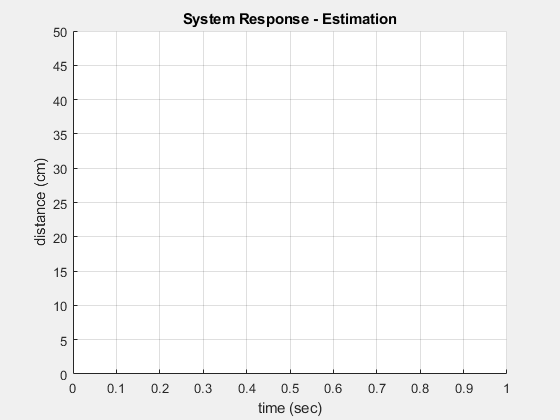

close all;
figure;
set(gcf,'Visible','on')
h = animatedline('Color','r','LineWidth',1);
ylim([0, 50]);
xlabel('time (sec)');
ylabel('distance (cm)');
grid on;
title('System Response - Estimation')

## Collecting Estimation Data

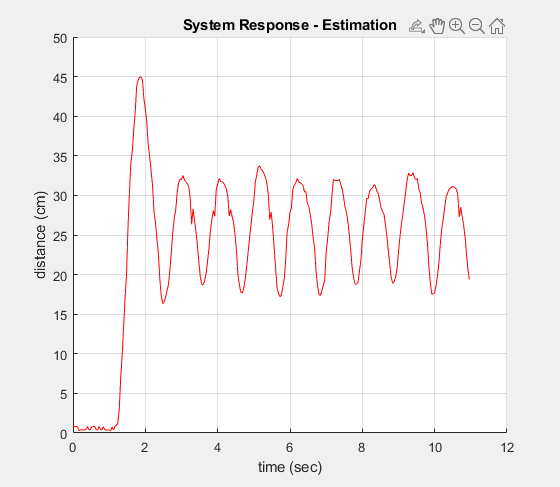

for i = 1:length(t)-1
    dis_est(i, 1) = 52 - (readDistance(ultrasonic) * 100);
    error = (setpoint(i) - dis_est(i,1));
    plant_IN = error * k;

    if plant_IN < lower_limit
        plant_IN = lower_limit/255;
    elseif plant_IN > upper_limit
        plant_IN = upper_limit/255;
    else
        plant_IN = (plant_IN/255);
    end

    writePWMDutyCycle(a,'D11',plant_IN);

    pause(step_time);

    addpoints(h, t(i), dis_est(i, 1));
    drawnow limitrate;
end

writePWMDutyCycle(a,'D11', 0);        % stopping the FAN

## Emergency Stop

writePWMDutyCycle(a,'D11', 0);        % stopping the FAN

## Plotting the Estimation result

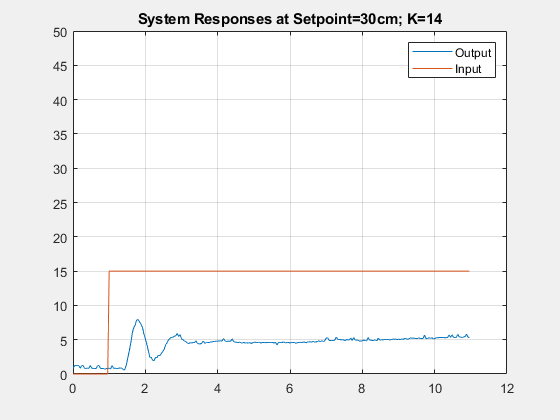

plot(t(1:end-1), dis_est(1:end-1))
ylim([0, 50]);
hold on;
plot(t(1:end-1), setpoint);
grid on;
title("System Responses at Setpoint=30cm; K=14");
legend("Output", "Input")
hold off;

## Validation Signal

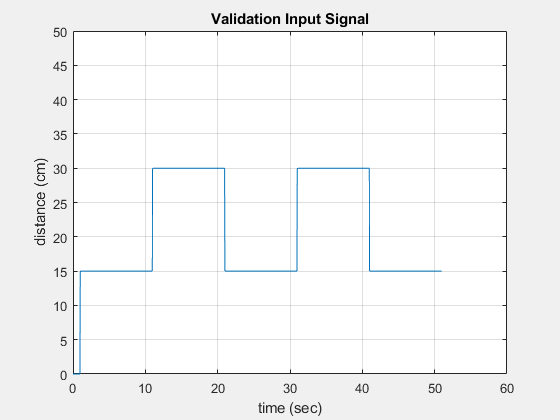

t_valid = 0:step_time:51;
dis_valid = zeros(length(t), 1);

a0 = zeros(1/step_time, 1);
a1 = 30*ones((1/step_time)*10, 1);
a2 = 40*ones((1/step_time)*10, 1);
a3 = 35*ones((1/step_time)*10, 1);
a4 = 25*ones((1/step_time)*10, 1);
a5 = 15*ones((1/step_time)*10, 1);

signal = [a0; a5; a1; a5; a1; a5];
plot(t_valid(1:end-1), signal)
ylim([0 50]);
grid on;
xlabel("time (sec)");
ylabel("distance (cm)");
title("Validation Input Signal")

## Setting up the plot Environment

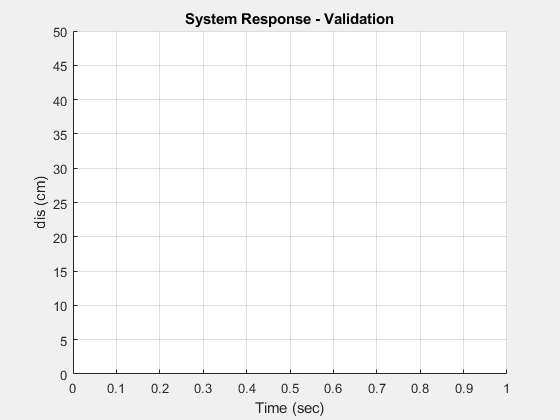

figure;
set(gcf,'Visible','on')
g = animatedline('Color','b','LineWidth',1);
ylim([0, 50]);
xlabel('Time (sec)');
ylabel('dis (cm)');
grid on;
title('System Response - Validation')

## Collecting Validation Data

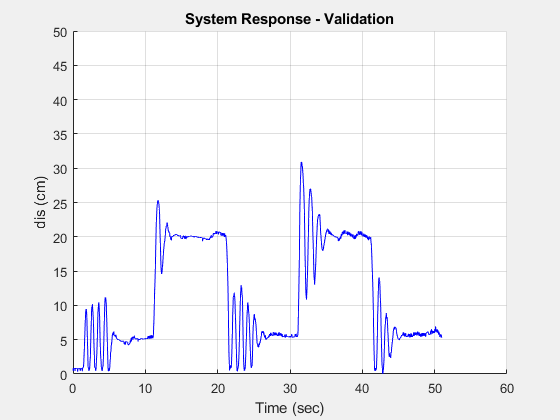

for i = 1:length(t_valid)-1
    dis_valid(i, 1) = 52 - (readDistance(ultrasonic) * 100);
    error = (signal(i) - dis_valid(i,1));
    plant_IN = error * k;

    if plant_IN < lower_limit
        plant_IN = lower_limit/255;
    elseif plant_IN > upper_limit
        plant_IN = upper_limit/255;
    else
        plant_IN = (plant_IN/255);
    end

    writePWMDutyCycle(a,'D11',plant_IN);

    pause(step_time);

    addpoints(g, t_valid(i), dis_valid(i, 1));
    drawnow limitrate;
end

writePWMDutyCycle(a,'D11', 0);        % stopping the FAN

## Plotting the Estimation result

size(t_valid)

ans =            1        1276


size(dis_valid)

ans =         1275           1


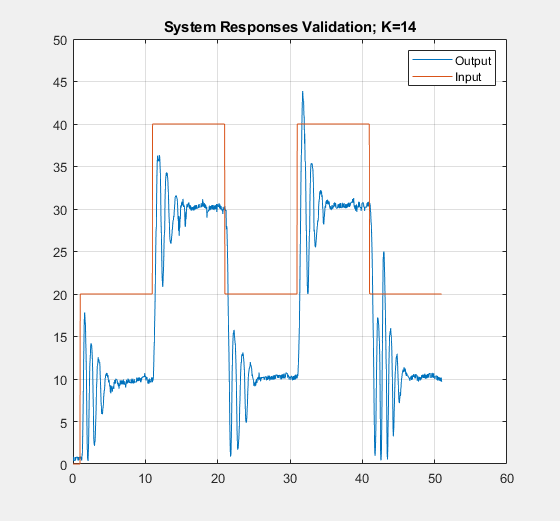

plot(t_valid(1:end-1), dis_valid)
hold on;
plot(t_valid(1:end-1), signal);
ylim([0 50]);
grid on;
title("System Responses Validation; K=14");
legend("Output", "Input")
hold off;

## saving varaibales to a MAT file

t_valid = t_valid(1:end-1);
t = t(1:end-1);
dis_est = dis_est(1:end-1);

save ("Run2_14_2.mat", "dis_est", "t", "dis_valid", "t_valid", "k", "signal", "setpoint");

## Deleting and clearing the objects

clear a ultrasonic